## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

load("AllMFPixPara_Paper2TuneFig1V4.mat")
%load("AllMFPixPara_Paper2Tune.mat")

If MF+v, run this section 

DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
%FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);
fLDE_OPT = load([DataFolder 'Paper2_LDE3_Fig1V4.mat'],'f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load([DataFolder 'Paper2_LDE2_Fig1V4.mat'],'f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load([DataFolder 'Paper2_LDE1_Fig1V4.mat'],'f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~(isempty(fLDE_OPT{LDEInd}) || size(fLDE_OPT{LDEInd},2)<25)
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_opt(FrLDE_opt<0) = eps;
FrLDE_obl(FrLDE_obl<0) = eps;
FrLDE_ort(FrLDE_ort<0) = eps;
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
    (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
    (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
    (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

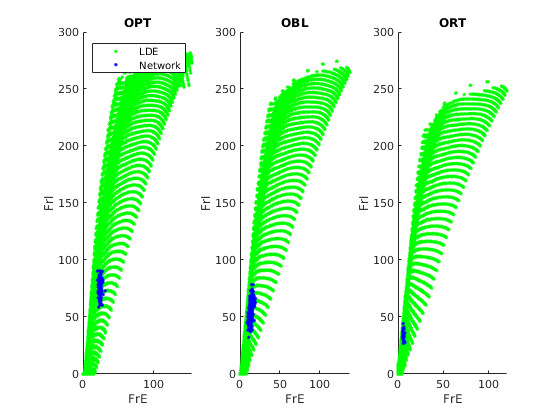

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
%scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
%scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
%scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

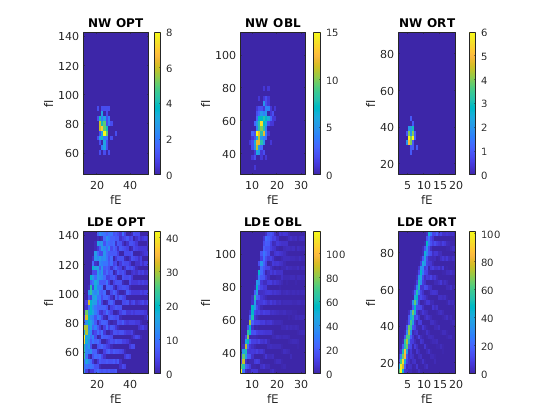


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

If LIF-only run this section

DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'];

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
OPTOBLBd_Pix = lambda_SOn_Pixel>0.33 & lambda_SOn_Pixel<0.42;
ORTOBLBd_Pix = lambda_SOn_Pixel>0.22 & lambda_SOn_Pixel<0.30;
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
%FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);
fLDE_OPT = load([DataFolder 'Paper2_LIFoLDE3_Fig1V4.mat'],'f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load([DataFolder 'Paper2_LIFoLDE2_Fig1V4.mat'],'f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load([DataFolder 'Paper2_LIFoLDE1_Fig1V4.mat'],'f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(3,length(fLDE_OPT));
FrLDE_obl = zeros(3,length(fLDE_OPT));
FrLDE_ort = zeros(3,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    if ~(isempty(fLDE_OPT{LDEInd}) || size(fLDE_OPT{LDEInd},2)<25)
        FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,10:end),2);
        FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,10:end),2);
        FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,10:end),2);
    else
        FrLDE_opt(:,LDEInd) = nan;
        FrLDE_obl(:,LDEInd) = nan;
        FrLDE_ort(:,LDEInd) = nan;
    end
end
FrLDE_opt(FrLDE_opt<0) = eps;
FrLDE_obl(FrLDE_obl<0) = eps;
FrLDE_ort(FrLDE_ort<0) = eps;
FrLDE_optE = (FrLDE_opt(1,:) * NSPix + FrLDE_opt(2,:) * NCPix)/(NSPix+NCPix);
FrLDE_oblE = (FrLDE_obl(1,:) * NSPix + FrLDE_obl(2,:) * NCPix)/(NSPix+NCPix);
FrLDE_ortE = (FrLDE_ort(1,:) * NSPix + FrLDE_ort(2,:) * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(3,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(3,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(3,:),XORT,YORT);


Figures for comparison

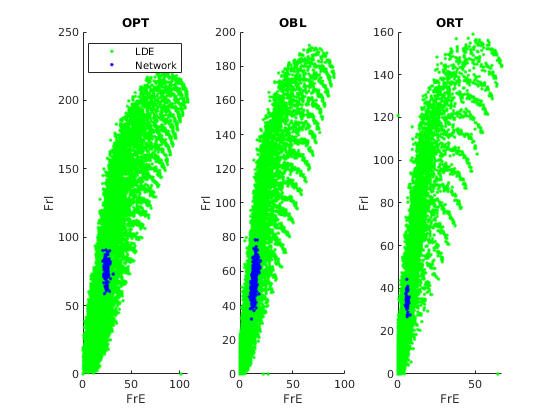

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(3,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
%scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(3,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
%scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(3,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
%scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

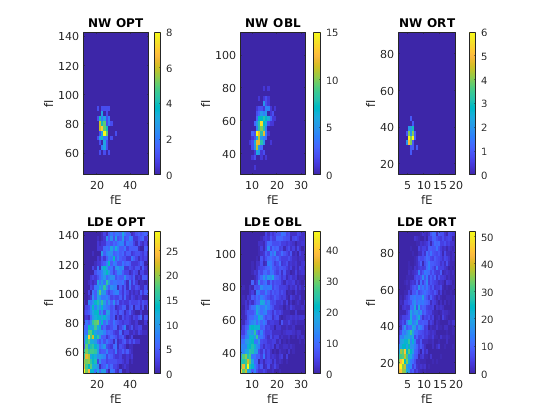


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

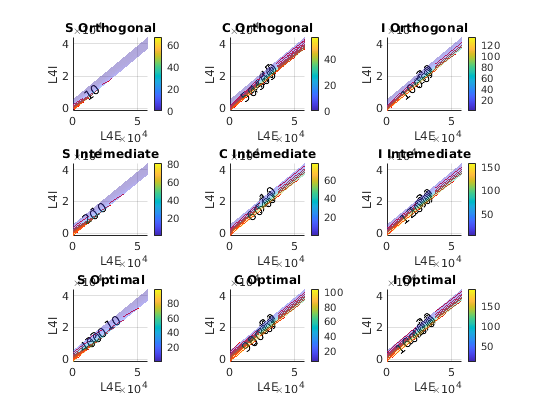

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
% L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
% for PInd = 1:N_HC*NPixX*N_HC*NPixY
%     L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
%     L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
%     L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
% end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
load(['Paper2_LIFoLDE1_Fig1V4.mat'])
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);

MFv = false;
if MFv 
    LIFN = 5;
else
    LIFN = 3;
end
figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['Paper2_LIFoLDE' num2str(Ctgr) '_Fig1V4.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),LIFN);
    for LDEInd = 1:length(f_EnIOut)
        if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    FrLDE(FrLDE<0) = eps;
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,true,MFv );

    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true,true,MFv );

    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true,true,MFv );
end

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

Maybe linear extrapolation?

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 3; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

PixL6Ctgr = LGNIndSpat(L6SFilt,unique(L6S_Drive),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(PhaseFRS(OD_S)',unique(PhaseFRS(OD_S)),NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
% Classify Input for each pixel
% Get input spatial pattern for 3*3 and make a larger one

% PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
% PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixInptCtgr,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY)

% CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
% cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
% colormap(CtgrMap)

Give an intial condition, Now start

try a dot product here

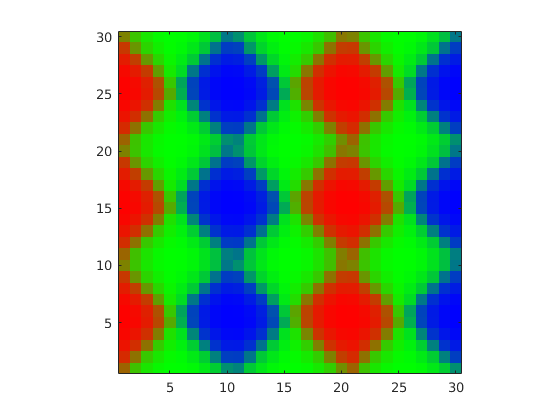

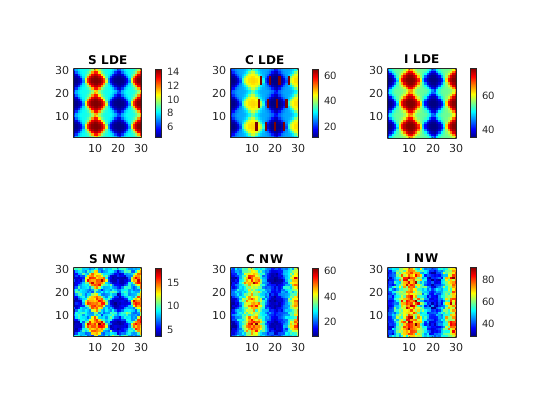

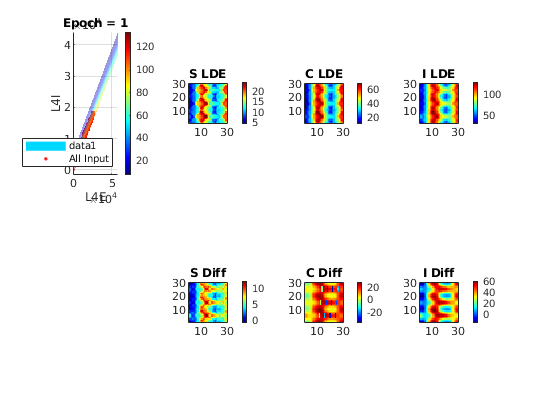

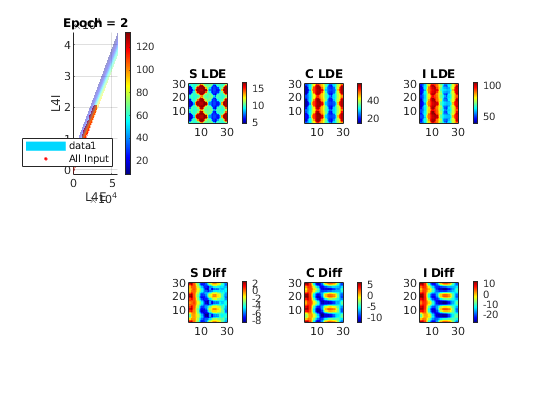

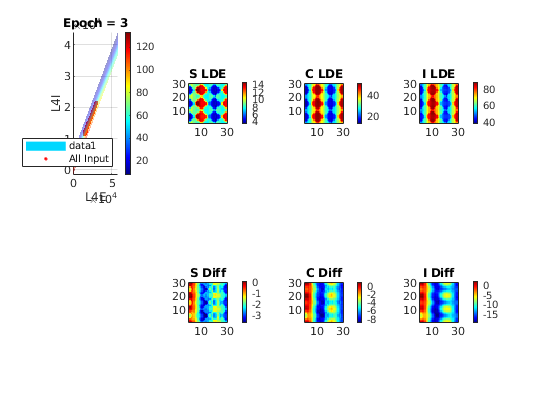

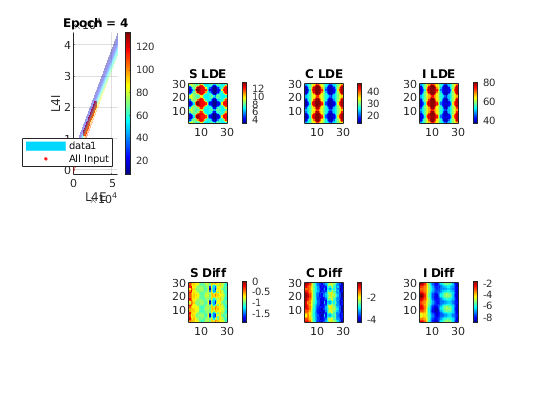

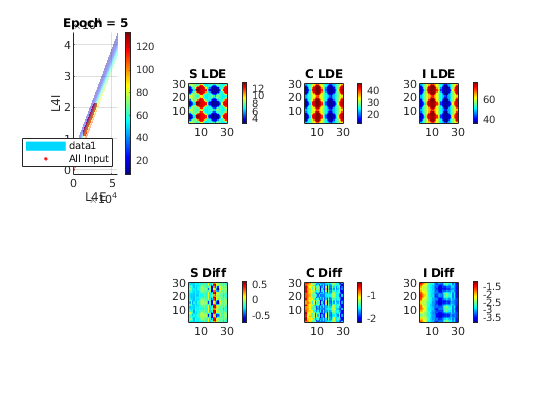

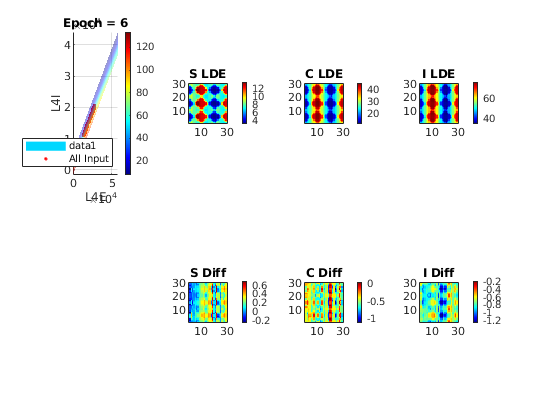

ORTPixLar = PixInptCtgr(:,1) == 1;
OBLPixLar = PixInptCtgr(:,2) == 1;
OPTPixLar = PixInptCtgr(:,3) == 1;
MeanFrCtry = @(x1) [mean(x1(ORTPix)),mean(x1(OBLPix)),mean(x1(OPTPix))];
% MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
%                      mean(x1(OBLPix)),...
%                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end
% LDEIni.S = ORTPix*mean(FrSPixVec(ORTPix)) + OBLPix*mean(FrSPixVec(OBLPix)) + ...
%            OPTPix*mean(FrSPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrSPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrSPixVec(OPTOBLBd_Pix));
% LDEIni.C = ORTPix*mean(FrCPixVec(ORTPix)) + OBLPix*mean(FrCPixVec(OBLPix)) + ...
%            OPTPix*mean(FrCPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrCPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrCPixVec(OPTOBLBd_Pix));
% LDEIni.I = ORTPix*mean(FrIPixVec(ORTPix)) + OBLPix*mean(FrIPixVec(OBLPix)) + ...
%            OPTPix*mean(FrIPixVec(OPTPix)) + ORTOBLBd_Pix*mean(FrIPixVec(ORTOBLBd_Pix)) + ...
%            OPTOBLBd_Pix*mean(FrIPixVec(OPTOBLBd_Pix));


% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    figure('Name','LDE Iteration')
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    subplot 241
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
    hold on
    scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
    %     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
    %     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
    %     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
    %     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
    %     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
    legend('Location','southeast')
    title(sprintf('Epoch = %d', Epc))
    hold off
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
        L4EUse,L4IUse,LDEUse.S,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
        L4EUse,L4IUse,LDEUse.C,...
        PixInptCtgr);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc(L4EmeshX, L4ImeshY,...
        LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
        L4EUse,L4IUse,LDEUse.I,...
        PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
    subplot 242
    ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
    subplot 243
    ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
    subplot 244
    ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
    subplot 246
    ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
    subplot 247
    ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
    subplot 248
    ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
    drawnow
    pause(0.5)
end

One more fig for diff

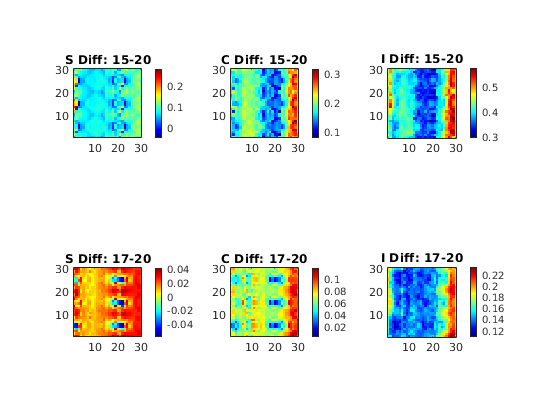

figure('Name','epoch diff')
subplot 231
Ep1 = 15; Ep2 = 17; Ep3 = 20;
ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
subplot 232
ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
subplot 233
ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))

subplot 234
ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
subplot 235
ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
subplot 236
ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
    N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

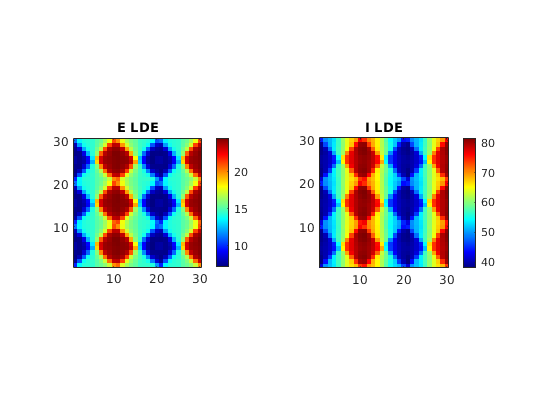


figure('Name','EImap')
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')

 Compute Frs

LDENames = fieldnames(LDEOut)

LDENames = 3×1 cell array
    {'S'}
    {'C'}
    {'I'}


for Nid = 1:length(LDENames)
    CurrField = LDEOut.(LDENames{Nid});
    CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
    CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
    LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
    MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
end

ans =     4.6881    8.7386   14.2966


ans =    13.6752   29.6853   46.5666


ans =    39.3579   59.4099   79.9702


## 4. Comparison between MF+V and LIF-only

L4lifSE = C_SS_Pixel_Us*FrSPixVec + C_SC_Pixel_Us*FrCPixVec;
L4lifSI = C_SI_Pixel_Us*FrIPixVec ;
L4lifCE = C_CS_Pixel_Us*FrSPixVec + C_CC_Pixel_Us*FrCPixVec;
L4lifCI = C_CI_Pixel_Us*FrIPixVec ;
L4lifIE = C_IS_Pixel_Us*FrSPixVec + C_IC_Pixel_Us*FrCPixVec;
L4lifII = C_II_Pixel_Us*FrIPixVec ;
L4localSE = diag(C_SS_Pixel_Us).*FrSPixVec + diag(C_SC_Pixel_Us).*FrCPixVec;
L4localSI = diag(C_SI_Pixel_Us).*FrIPixVec ;
L4localCE = diag(C_CS_Pixel_Us).*FrSPixVec + diag(C_CC_Pixel_Us).*FrCPixVec;
L4localCI = diag(C_CI_Pixel_Us).*FrIPixVec ;
L4localIE = diag(C_IS_Pixel_Us).*FrSPixVec + diag(C_IC_Pixel_Us).*FrCPixVec;
L4localII = diag(C_II_Pixel_Us).*FrIPixVec ;
L4EmfvUse = C_SS_Pixel_Us*FrSPixVec +... - diag(C_SS_Pixel_Us).*FrSPixVec + ...
            C_CS_Pixel_Us*FrSPixVec +... - diag(C_CS_Pixel_Us).*FrSPixVec + ...
            C_IS_Pixel_Us*FrSPixVec +... - diag(C_IS_Pixel_Us).*FrSPixVec + ...
            C_SC_Pixel_Us*FrCPixVec +... - diag(C_SC_Pixel_Us).*FrCPixVec + ...
            C_CC_Pixel_Us*FrCPixVec +... - diag(C_CC_Pixel_Us).*FrCPixVec + ...
            C_IC_Pixel_Us*FrCPixVec ;% - diag(C_IC_Pixel_Us).*FrCPixVec ;
L4ImfvUse = C_SI_Pixel_Us*FrIPixVec +... - diag(C_SI_Pixel_Us).*FrIPixVec + ...
            C_CI_Pixel_Us*FrIPixVec +... - diag(C_CI_Pixel_Us).*FrIPixVec + ...
            C_II_Pixel_Us*FrIPixVec ;% - diag(C_II_Pixel_Us).*FrIPixVec ;

Now consider a pixel containing 3 neurons: S C I

Pick up 10 pixels

%InputCtgrList = [1,1, 1,  2,  2,  2,   3,  3,   3];
%PixRow = [5,5,25,  1,10,20,  5,15,5 ];
PixRow = randi([1,30],50,1);
%PixCol = [1,20,20, 15,15,26, 10,10,29];
PixCol = randi([1,30],50,1);
PixIndList = (PixCol-1)*N_HC*NPixY +  PixRow ;% [7,55,615,180,450,645, 565,326, 276];
VRcdAll = cell(size(PixIndList));
SpRcdAll = cell(size(PixIndList));
FrRcdAve = zeros(length(PixIndList),3);

for LIFtestInd = 1:length(PixIndList)
%InputCtgr = InputCtgrList(LIFtestInd); 
PixInd = PixIndList(LIFtestInd); % pixel and input category

FL6_One = unique(L6Ord_F)/1e3;
rL6SU = L6S_Pixel(PixInd);
rL6CU = L6C_Pixel(PixInd);
rL6IU = L6I_Pixel(PixInd);
L4SE = L4lifSE(PixInd)/1e3*(1-p_EEFail); L4CE = L4lifCE(PixInd)/1e3*(1-p_EEFail); L4IE = L4lifIE(PixInd)/1e3;
L4SI = L4lifSI(PixInd)/1e3;              L4CI = L4lifCI(PixInd)/1e3;              L4II = L4lifII(PixInd)/1e3;

LIFSimuT = 50*1e3; TimeFrac = 1/(LIFSimuT/1e3)/LGNFreq;
lgn_Events    = PoissonInputForNetwork(3, 45*[N_Slgn;N_Clgn;N_Ilgn]/1e3 ,LIFSimuT*TimeFrac,dt,true);
AmbPix_Events = PoissonInputForNetwork(3,[rS_amb;rC_amb;rI_amb],LIFSimuT*TimeFrac,dt,true);
L6Pix_Events  = PoissonInputForNetwork(3,[rL6SU; rL6CU; rL6IU], LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsE = PoissonInputForNetwork(3,[L4SE; L4CE; L4IE],LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsI = PoissonInputForNetwork(3,[L4SI; L4CI; L4II],LIFSimuT*TimeFrac,dt,true);
gL = [gL_E*ones(2,1); gL_I*ones(1)];

Can precompute all Gs...

% Now adjust lgn to S
lgn_SOnOff = [0.045, 0.0675, 0.09;
              0.045, 0.0225, 0.00];
lgn_Slif = [lambda_SOn_Pixel';lambda_SOff_Pixel'];
lgn_Slifort = mean(mean(lgn_Slif))*ones(2,1);

lgnAdj = lgn_Slif(:,PixInd)./lgn_Slifort;
lgnAdjU = reshape(repmat(lgnAdj,1,floor(size(L4Pix_EventsE,2)/2))', 1, 2*floor(size(L4Pix_EventsE,2)/2));

Disp some # of spikes

% sprintf('#L6 = %.4f', sum(FL6_One.*PixL6Ctgr(PixInd,:)))
% sprintf('#L4SE total = %.4f, #L4SI total = %.4f',L4lifSE(PixInd)/1e3,L4lifSI(PixInd)/1e3)
% sprintf('#L4CE total = %.4f, #L4CI total = %.4f',L4lifCE(PixInd)/1e3,L4lifCI(PixInd)/1e3)
% sprintf('#L4IE total = %.4f, #L4II total = %.4f',L4lifIE(PixInd)/1e3,L4lifII(PixInd)/1e3)
% sprintf('#L4SE local = %.4f, #L4SI local = %.4f',L4localSE(PixInd)/1e3,L4localSI(PixInd)/1e3)
% sprintf('#L4CE local = %.4f, #L4CI local = %.4f',L4localCE(PixInd)/1e3,L4localCI(PixInd)/1e3)
% sprintf('#L4IE local = %.4f, #L4II local = %.4f',L4localIE(PixInd)/1e3,L4localII(PixInd)/1e3)

For each cycle, initiate a new start

TCyc = floor(1/TimeFrac);
VRcdCyc = cell(TCyc,1);
SpRcdCyc = cell(TCyc,1);

RefTimer = zeros(3, 1); % initiate the timer of ref
vt = zeros(3, 1); 
tic
for TInt = 1:TCyc
    VRcd = zeros(size(L4Pix_EventsE));
    SpLIF = zeros(3, 1);

    % New Gs
    lgnPix_Events = lgn_Events(:,randperm(size(lgn_Events,2)));
    lgnPix_Events(1,1:length(lgnAdjU)) = lgnPix_Events(1,1:length(lgnAdjU)).*lgnAdjU;

    winAMPA = 0:dt:tau_ampa_D*3;
    winNMDA = 0:dt:tau_nmda_D*3;
    winGABA = 0:dt:tau_gaba_D*3;
    KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
    KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
    KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
    KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
    KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
    KerGABA = KerGABA / (sum(KerGABA)*dt);
    % Incorporate L4 and other input
    ampaInp = single(...
          [S_Elgn * lgnPix_Events(1:2,:);            S_Ilgn * lgnPix_Events(3,:)]...
        +  S_amb * AmbPix_Events ... % S_amb identical for E and I
        + [S_EL6 * L6Pix_Events(1:2,:) * rhoE_ampa;  S_IL6 * L6Pix_Events(3,:) * rhoI_ampa]...
        + [S_EE  * L4Pix_EventsE(1:2,:) * rhoE_ampa; S_IE * L4Pix_EventsE(3,:) * rhoI_ampa]);
    nmdaInp = single(...
          [S_EL6 * L6Pix_Events(1:2,:) * rhoE_nmda;  S_IL6 * L6Pix_Events(3,:) * rhoI_nmda]...
        + [S_EE  * L4Pix_EventsE(1:2,:) * rhoE_nmda; S_IE * L4Pix_EventsE(3,:) * rhoI_nmda]);
    gabaInp = single(...
          [S_EI * L4Pix_EventsI(1:2,:);              S_II * L4Pix_EventsI(3,:)] );
    %% Precompute All Conductances: Speed up by ifft/fft
    n = size(ampaInp,2);
    GAMPA = ifft(fft(ampaInp',n) .* repmat(fft(KerAMPA',n),1,3))';
    GNMDA = ifft(fft(nmdaInp',n) .* repmat(fft(KerNMDA',n),1,3))';
    GGABA = ifft(fft(gabaInp',n) .* repmat(fft(KerGABA',n),1,3))';

    GE = GAMPA + GNMDA;  GI = GGABA;
    
    for tInd = 1:size(L4Pix_EventsE,2)
        % Firstly, refrectory neurons get out if timer reachs t_ref
        RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
        vt(RefTimer>=tau_ref) = 0;
        RefTimer(RefTimer>=tau_ref) = 0;

        ov  = vt + dt*(-gL.*vt - GE(:,tInd).*(vt-Ve) - GI(:,tInd).*(vt-Vi));
        SpNow = single(ov>=1);
        ov(ov>=1) = nan;
        VRcd(:,tInd) = ov;
        % Compute meanV
            SpLIF = SpLIF + SpNow;
        % Transfer variables
        vt = ov;
    end
    VRcdCyc{TInt} = VRcd;
    SpRcdCyc{TInt} = SpLIF;
end
toc
VRcdAll{LIFtestInd} = VRcdCyc;
SpRcdAll{LIFtestInd} = SpRcdCyc;
SpRcdMat = cell2mat(SpRcdCyc')';
FrRcdAve(LIFtestInd,:) = mean(SpRcdMat(10:end,:))*LGNFreq; % The actual firing rates
%LDEresults = zeros(length(FrSPixVec),3);
end

Elapsed time is 3.604490 seconds.
Elapsed time is 3.532574 seconds.
Elapsed time is 3.556189 seconds.
Elapsed time is 3.535762 seconds.
Elapsed time is 3.524127 seconds.
Elapsed time is 3.537323 seconds.
Elapsed time is 3.521880 seconds.
Elapsed time is 3.536309 seconds.
Elapsed time is 3.563148 seconds.
Elapsed time is 3.565877 seconds.
Elapsed time is 3.546851 seconds.
Elapsed time is 3.540331 seconds.
Elapsed time is 3.553830 seconds.
Elapsed time is 3.536009 seconds.
Elapsed time is 3.558530 seconds.
Elapsed time is 3.553268 seconds.
Elapsed time is 3.565033 seconds.
Elapsed time is 3.533059 seconds.
Elapsed time is 3.549058 seconds.
Elapsed time is 3.555889 seconds.
Elapsed time is 3.550451 seconds.
Elapsed time is 3.531589 seconds.
Elapsed time is 3.545666 seconds.
Elapsed time is 3.542945 seconds.
Elapsed time is 3.543872 seconds.
Elapsed time is 3.521670 seconds.
Elapsed time is 3.537308 seconds.
Elapsed time is 3.549907 seconds.
Elapsed time is 3.552710 seconds.
Elapsed time i

Now for LDE results

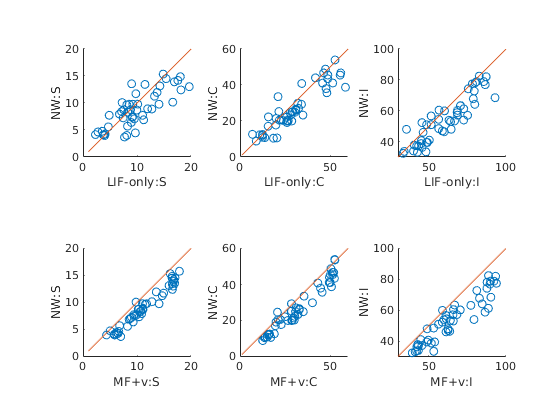

DirLDEresults(:,1) = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.S,...
    PixInptCtgr);
%ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,2)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.C,...
    PixInptCtgr);
% ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,3)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.I,...
    PixInptCtgr);

FrLDEDir = DirLDEresults(PixIndList,:);

FrNW = [FrSPixVec(PixIndList),FrCPixVec(PixIndList),FrIPixVec(PixIndList)];

figure('Name','LIF-only results')
subplot 231
scatter(FrRcdAve(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-only:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 232
scatter(FrRcdAve(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-only:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 233
scatter(FrRcdAve(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-only:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

subplot 234
scatter(FrLDEDir(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 235
scatter(FrLDEDir(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 236
scatter(FrLDEDir(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

A figure showing all the details

close all
TRcdSteps = 1/4:1/4:LIFSimuT/1e3;
DomName = {'ort','obl','opt'};
for PlotInd = 1:9
    SpRcdU = SpRcdAll{PlotInd};
    SpRcdU = cell2mat(SpRcdU');
    figure(1)
    % For each subplot
    subplot(3,3,PlotInd)
    hold on
    plot(TRcdSteps,SpRcdU(1,:)*LGNFreq,'r','DisplayName','S-LIF')
    plot(TRcdSteps,SpRcdU(2,:)*LGNFreq,'g','DisplayName','C-LIF')
    plot(TRcdSteps,SpRcdU(3,:)*LGNFreq,'b','DisplayName','I-LIF')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('T (s)'); ylabel('Frs'); ylim([0 120])
    title(['OD:', DomName{InputCtgrList(PlotInd)}])
    if PlotInd == 1
        legend
    end
    
    L4EPixU = L4EmfvUse(PixIndList(PlotInd))
    L4IPixU = L4ImfvUse(PixIndList(PlotInd))
    LDEInd = find(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU) == min(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU),[],'all'))
    InputCtgrList(PlotInd)
    if InputCtgrList(PlotInd) == 3
        fMFV = fLDE_OPT{LDEInd};
    elseif InputCtgrList(PlotInd) == 2
        fMFV = fLDE_OBL{LDEInd};
        
    elseif InputCtgrList(PlotInd) == 1
        fMFV = fLDE_ORT{LDEInd};
        
    end
    
    fMFV(fMFV<0) = eps;
    figure(2)
    subplot(3,3,PlotInd)
    hold on
    plot((fMFV(1,:)+fMFV(3,:))/2,'r','Marker','o','DisplayName','S-MFV')
    plot((fMFV(2,:)+fMFV(4,:))/2,'g','Marker','o','DisplayName','C-MFV')
    plot(fMFV(5,:),'b','Marker','o','DisplayName','I-MFV')
    plot(1:60,ones(size(1:60))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(1:60,ones(size(1:60))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(1:60,ones(size(1:60))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('epochs');ylim([0 120]);xlim([0 60])
    if PlotInd == 1
        legend
    end
end

